# CUMCM 2020A 炉温曲线--讲评

摘自“Matlab 创新奖”的获奖者论文

## 问题背景

`随着电子产品的竞争日趋加剧，其生成过程的不确定性也不断加大，这给电子产品的贴装、焊装提出了更高的要求。在集成电路板等电子产品生产中，``需要``将安装有各种电子元件的印刷电路板放置在回焊炉中，通过加热``，``将电子元件自动焊接到电路板上。在这个生产过程中，让``回焊炉``的各部分保持工艺要求的温度，对产品质量至关重要。因此，回焊炉各温区的温度控制技术和焊接工艺是回焊炉最关键的部分。本题旨在通过机理模型来进行分析研究。`

`命题人：广西大学 陈良、吕跃进`

`研究对象：回焊炉、PCB 电路板`

`问题重点：温度变化的机理模型`

[`回焊炉的基本原理`](https://zhuanlan.zhihu.com/p/396017467)

热传递的方式：

热传导：物体各部分之间不发生相对位移，依靠原子、分子、自由电子等微观粒子的热运动产生的热能传递

Fourier定律：$\phi = -k A\frac{dT}{dX}$

热对流：流体流过物体表面并与之发生热能的传递

Newton 冷却定律：$\phi = hA(t_w-t_f)$

热辐射：物体通过电磁波传递能量

Stenfan-Boltzmann定律：$\phi = A\sigma T^4$

## 问题重述

- 问题一：`根据焊接区域的温度变化规律建立数学模型，在建立的数学模型基础上，给定传送带过炉速度和各温区温度的情况下，给出焊接区域中心的温度变化情况，列出小温区`3`、`6`、`7`中点及小温区`8`结束处焊接区域中心的温度，画出相应的炉温曲线，并存储焊接区域中心的温度。`

- 问题二：`在给定的各温区温度的情况下，同时考虑制程界限约束，确定允许的最大传送带过炉速度。`

- 问题三：`要求超过`217º`C``到峰值温度所覆盖的面积最小，确定最优炉温曲线，以及各温区的设定温度和传送带的过炉速度，并给出相应的面积。`

- 问题四：`结合问题三，要求以峰值温度为中心线的两侧超过``217`º`C的炉温曲线应尽量对称以完善最优炉温曲线，并计算各温区设定的温度及传送带过炉速度，并给出相应的指标值。`

## 问题分析

- 针对问题一：`根据温度变化规律建立数学模型，目前大多数基于数据驱动的控制和调整，而缺乏机理模型。为了了解电路板在回焊炉内的物理过程，同时合理模拟各温区的温度变化曲线，拟在热传导方程和牛顿冷却定律的基础上建立数学模型，并基于最小二乘法和粒子群算法识别模型的待定参数。`

- 针对问题二：`根据第一问的结果，先通过二分法求得最大速度的大致区间，再遍历搜索，最后获得最大传送带过炉速度。`

- 针对问题三：`本问涉及变量个数较多，不宜采用搜索法，故采用模拟退火算法进行求解。`

- 针对问题四：`本问难点在于如何给定对称性指标，且属于多目标优化问题，拟采用动态综合加权法，将其化为单目标问题进行求解。`

## 问题一的模型建立

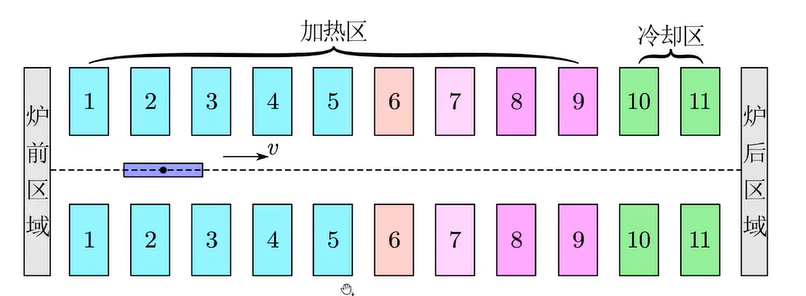

直角坐标系

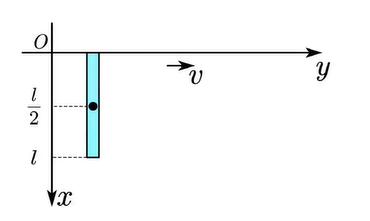

由Fourier定律和Newton冷却定律可以推导出一维热传导方程


$$\frac{\partial u}{\partial t} = a^2 \frac{\partial^2 u}{\partial x^2}\qquad \left(x\in \left[0,l\right], t\in\left[0,\frac{L}{v}\right]\right)\\$$


假设1：焊接区域内部只有热传导，忽略热辐射

假设2：焊接区域边界只有热对流，忽略热辐射

定解条件：

- 初值条件：$u(x,0) = u_0$

- 边界条件：$\begin{cases}
-\frac{\partial u}{\partial x}(0,t)+\sigma u(0,t) = \sigma u_e\\
\frac{\partial u}{\partial x}(l,t)+\sigma u(l,t) = \sigma u_e\\
\end{cases}$

`焊接区域中心的温度`$u\left(\frac{l}{2},t\right)$

空气温度场$u_e(x)=u_e(vt)=f(t)$

综上，数学模型为


$$\begin{cases}
\frac{\partial u}{\partial t} = a^2 \frac{\partial^2 u}{\partial x^2},\left(x\in \left[0,l\right], t\in\left[0,\frac{L}{v}\right]\right)\\
u(x,0) = u_0, x\in \left[0,l\right]\\
-\frac{\partial u}{\partial x}(0,t)+\sigma u(0,t) = \sigma u_e\\
\frac{\partial u}{\partial x}(l,t)+\sigma u(l,t) = \sigma u_e\\
u_e(x)=u_e(vt)=f(t)\\
\end{cases}$$


**空气温度场**$u_e(x)$**的确定**

题设：`回焊炉启动后，炉内空气温度会在短时间内达到稳定`

`假设3：回焊炉内，在垂直于传送带的截面上温度相同`


$$0=\frac{\partial u}{\partial t} = a^2 \frac{\partial^2 u}{\partial x^2} \rightarrow \frac{\partial^2 u}{\partial x^2} =0$$


syms u(x)
eqn = diff(u,x,2) == 0;
u_e(x) = dsolve(eqn)

$$u\_e(x) = C_{2}+C_{1}\,x$$

稳定后的炉内温度是线性变化的。

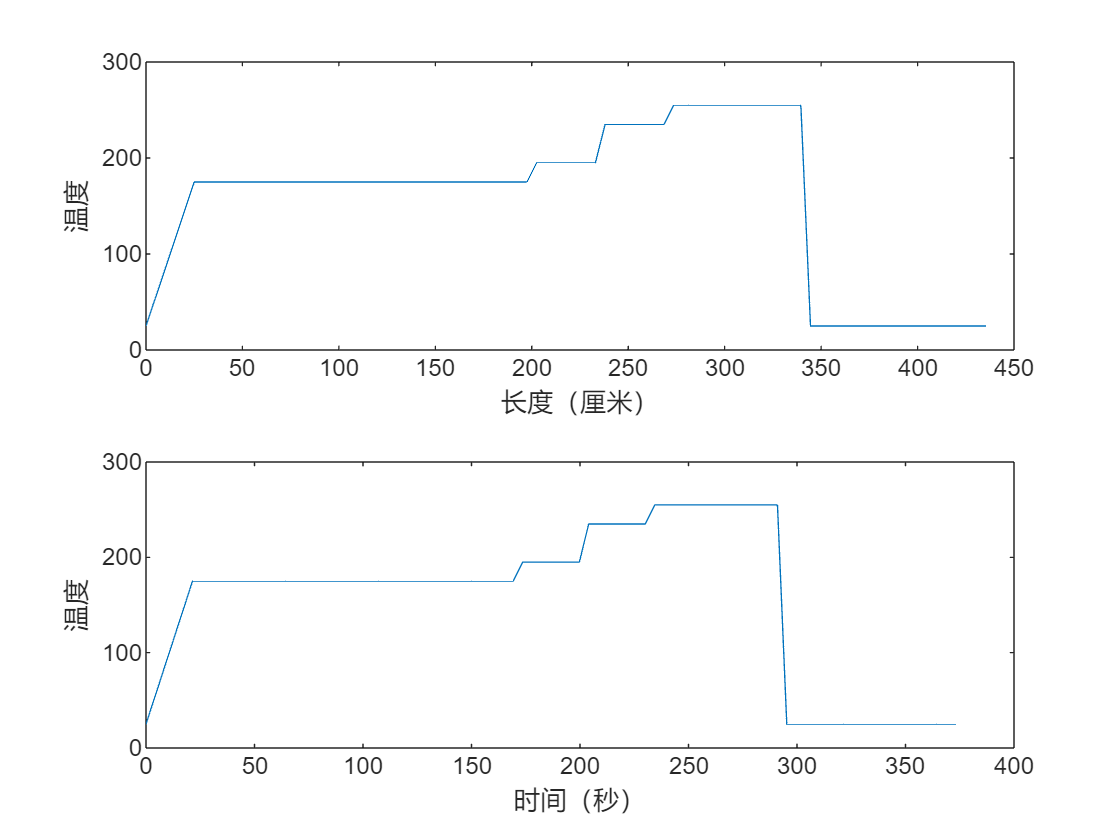

x = 0:0.01:435.5;
t = x/70*60;
y = EnvTem(x);
subplot(211)
plot(x,y)
xlabel('长度（厘米）')
ylabel('温度')
subplot(212)
plot(t,y)
xlabel('时间（秒）')
ylabel('温度')

## **问题一的模型求解**

热传导方程的数值求解

有限差分法：显式格式、隐式格式、C-N格式

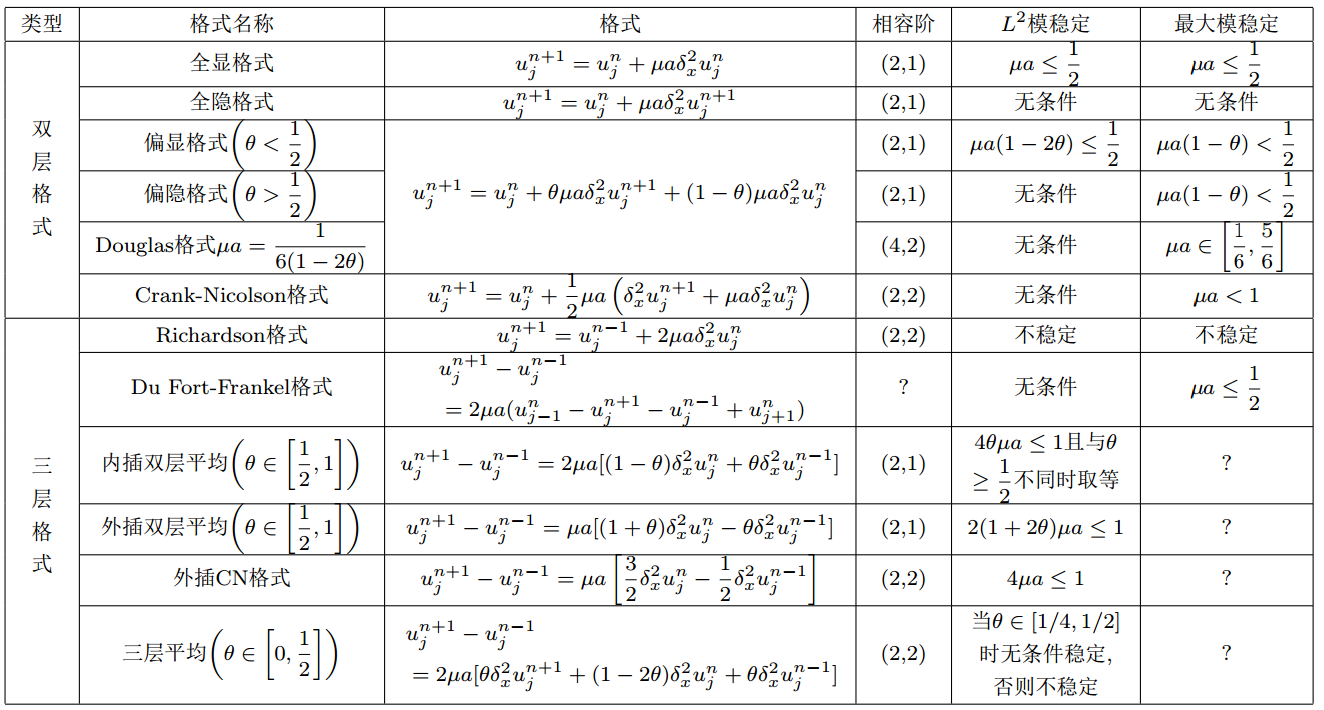

Crank-Nicolson 隐差分格式


$$u(x_i,t_j) = u_i^j\\
 \frac{ \partial u }{\partial t} (x_i,t_j)\approx  \frac{u_i^{j+1}-u_i^{j}}{\Delta t}\\
 \frac{\partial^2 u}{\partial x^2}(x_i,t_j)\approx  \frac{u_{i+1}^j-2u_i^{j}+u_{i-1}^j}{(\Delta x)^2}\\
\frac{u_i^{j+1}-u_i^{j}}{\Delta t} = \frac{a^2}{2}  \frac{u_{i-1}^j-2u_i^{j}+u_{i+1}^j+u_{i-1}^{j+1}-2u_i^{j+1}+u_{i+1}^{j+1}}{(\Delta x)^2}\\
u^0_i = u_0 \quad (i=1,\ldots,m)\\
- \frac{u_2^{j+1}-u_1^{j+1}}{\Delta x}+\sigma u_1^{j+1}=\sigma f(j+1)\\
 \frac{u_{m+1}^{j+1}-u_m^{j+1}}{\Delta x}+\sigma u_m^{j+1}=\sigma f(j+1)$$



$$r = \frac{a^2\Delta t}{(\Delta x)^2}
$$


C-N隐格式可改写为


$$-ru_{i-1}^{j+1}+2(1+r)u_i^{j+1}-ru_{i+1}^{j+1}=ru_{i-1}^j+2(1-r)u_i^{j}+ru_{i+1}^j\\
(1+\Delta x \sigma)u_1^{j+1}-u_2^{j+1}=\Delta x\sigma f(j+1)\\
(1+\Delta x \sigma)u_{m+1}^{j+1}-u_m^{j+1}=\Delta x\sigma f(j+1)\\$$


[一维热传导方程Crank-Nicholson隐式差分求解](https://zhuanlan.zhihu.com/p/512618295)

未知参数的确定（热传导系数、对流换热系数）最小二乘法+基于粒子群优化


$$\min E(a,\sigma) = \sum_{i=1}^n(u^*(i)-u(i))^2$$


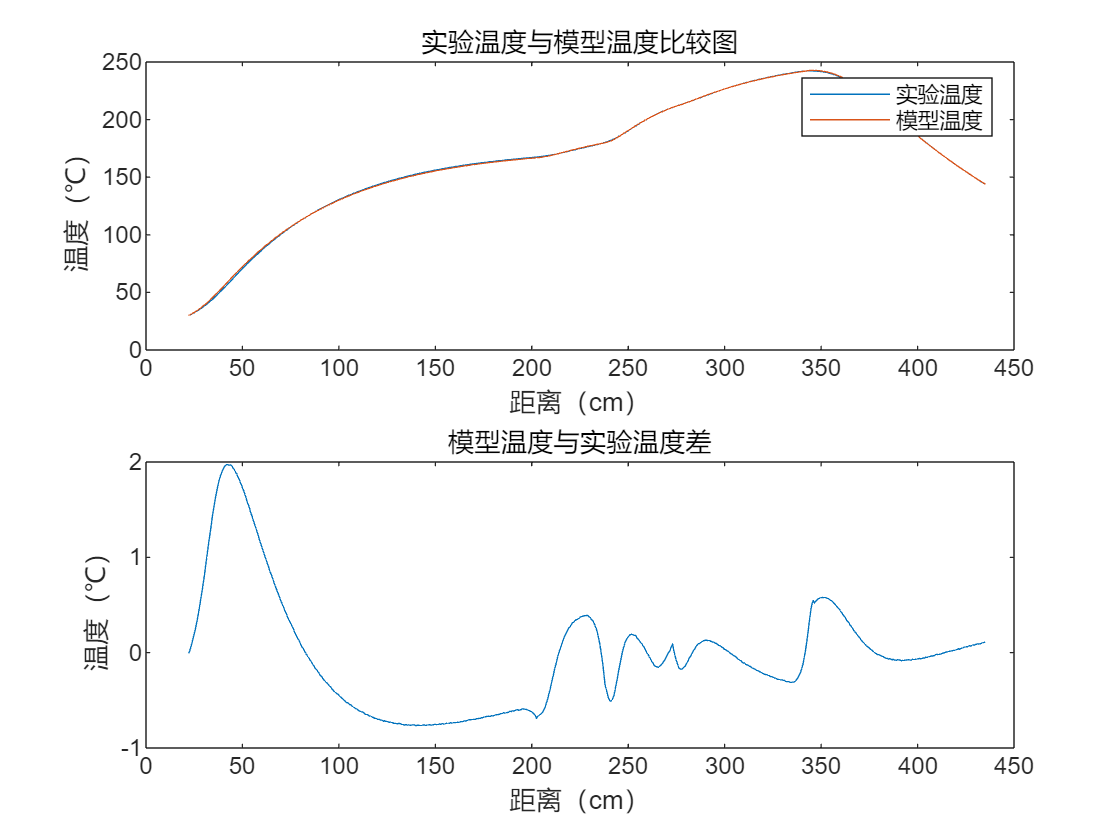

tic
A20200

toc

历时 286.811893 秒。


a = xm(1:5);
sig = xm(6:end);
T = table(categorical({'1-5';'6';'7';'8-9';'10-11'}),a,sig);
T.Properties.VariableNames = {'温区','热传导系数','对流换热系数'}

T = 5×3 table
    温区          热传导系数               对流换热系数     
    _____    ____________________    ____________________

    1-5      0.000667802430366541        851.767346102992
    6            28804.5967962908    0.000848210669975683
    7         0.00080841027322866        666.784620689611
    8-9          1498.02823512691    0.000527263590615201
    10-11    0.000968944356345075        1388.36816177033


save xm.mat xm

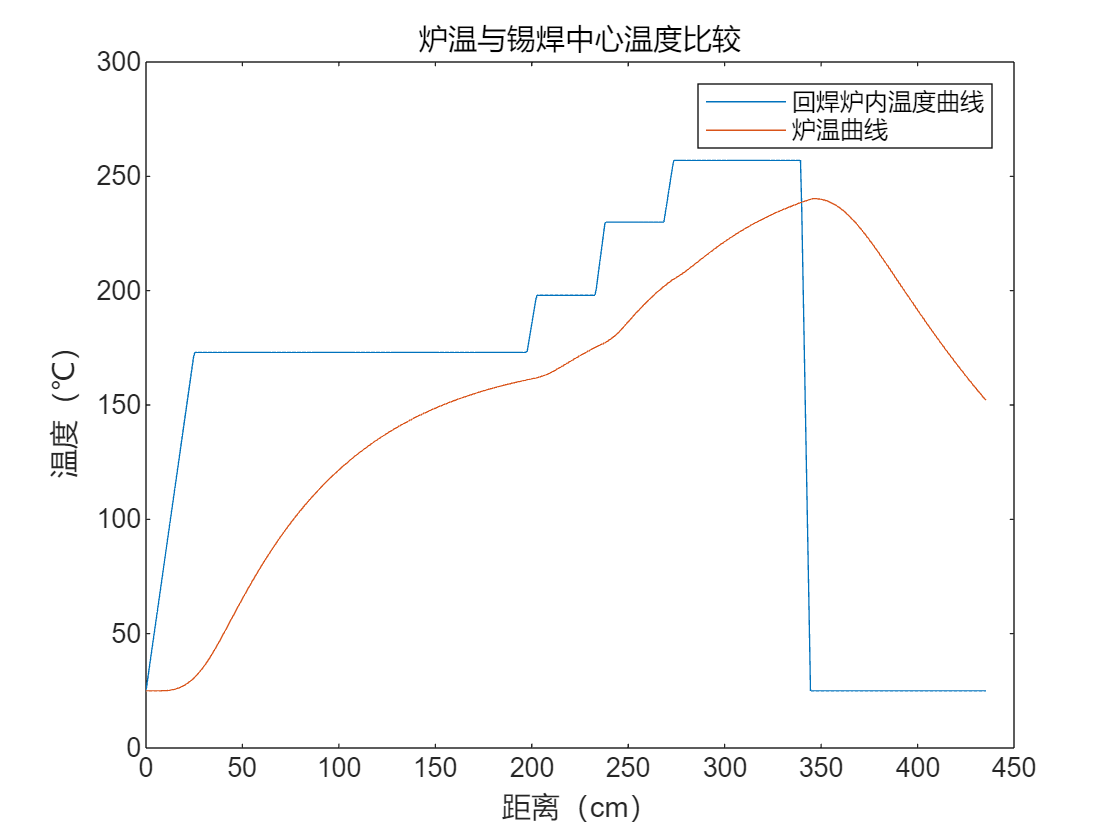

A20201

T = table(categorical({'温区3的中心';'温区6的中心';'温区7的中心';'温区8的中心'}),a');
T.Properties.VariableNames = {'位置','温度'}

T = 4×2 table
       位置             温度      
    __________    ________________

    温区3的中心     129.47243977127
    温区6的中心     167.96545744499
    温区7的中心    189.079646850745
    温区8的中心    223.455187071507


问题一用到的假设与符号

假设1：焊接区域内部只有热传导，忽略热辐射

假设2：焊接区域边界只有热对流，忽略热辐射

`假设3：回焊炉内，在垂直于传送带的截面上温度相同`

`假设4：电子元件及焊锡在水平方向没有热量传递`

`假设5：每个小温区内的温度视为常数`

符号：


$$锡焊厚度的方向变量：z \\
回焊炉的传输速度：v \\
锡焊内部  x 处在 t 时刻的温度: u(x,t)\\
回焊炉内的稳定温度场: h(x)=h(vt)=f(t)\\
锡膏热容: c \\
锡膏密度： \rho \\
锡膏热传导率：k \\
锡膏与空气的热交换系数: \zeta \\

a^2 = \frac{k}{c\rho}, \qquad \sigma = \frac{\zeta}{k}
$$


## **问题二的模型建立**

题设给定的制程界限

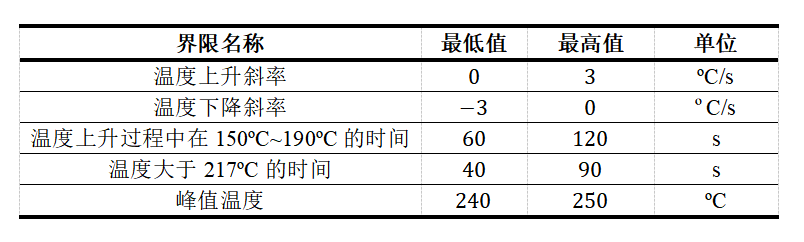

**建立模型** （线性规划模型）


$$\qquad \max v  \\
\text{使得}  \\
 \qquad \frac{|u_{i+1}-u_{i}|}{2}<3, 1\le i\le n\\
 \qquad 60\le T_1 \le 120\\
\qquad  40 \le T_2 \le 90 \\
\qquad  240 \le u_{\text{max}} \le 250$$


**求解模型** （二分法）


$$\qquad \max v_1  \\
\text{使得}  \\
 \qquad \frac{|u_{i+1}-u_{i}|}{2}<3, 1\le i\le n\\ \\

\qquad \max v_2  \\
\text{使得}  \\
 \qquad 60\le T_1 \le 120\\ \\

\qquad \max v_3  \\
\text{使得}  \\
\qquad  40 \le T_2 \le 90 \\ \\

\qquad \max v_4  \\
\text{使得}  \\
\qquad  240 \le u_{\text{max}} \le 250 \\ \\

\max v = \min(v_1,v_2,v_3,v_4)

$$


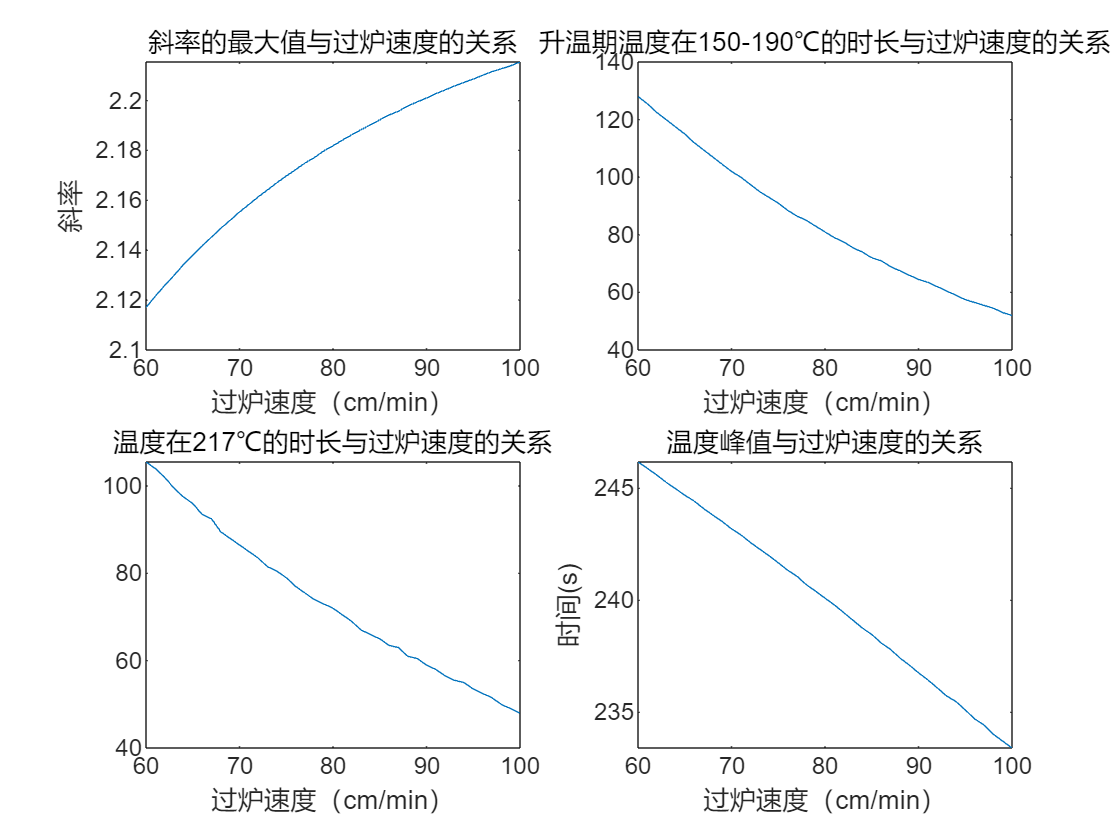

A20202

fprintf('最大传送带过炉速度: %.4f cm/min',v)

最大传送带过炉速度: 80.2448 cm/min

问题二用到的符号


$$温度上升过程中在150^{\circ}C-190^{\circ}C的时间：T_1 \\
温度大于217^{\circ}C时间：T_2 \\
温度峰值：u_{\max}$$


## **问题三的模型建立**

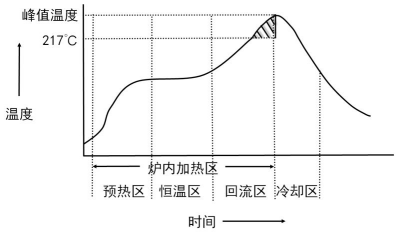


$$S_{阴影} = \int_{t_m}^{t_n}\left(u(x,t)-217\right)dt\\
\qquad\approx \left(\sum_{i=m}^{n-1}\frac{(u(t_i)-217)+(u(t_{i+1})-217)}{2}\right)\Delta t\\
\qquad = \left(\frac{u(t_m)+u(t_n)}{2}+\sum_{i=m+1}^{n-1}{(u(t_i)-217)}\right)\Delta t$$



$$\qquad \min_{F,v} S =  \left(\frac{u_m+u_n}{2}+\sum_{i=m+1}^{n-1}{(u_i-217)}\right)\Delta t  \\
\text{使得}  \\
 \qquad \frac{|u_{i+1}-u_{i}|}{2}<3, 1\le i\le n\\
 \qquad 60\le T_1 \le 120\\
\qquad  40 \le T_2 \le 90 \\
\qquad  240 \le u_{\text{max}} \le 250\\
\qquad |F-F_0|\le 10 \\
\qquad 65\le v \le 100$$


求解模型

历时 148.791293 秒。


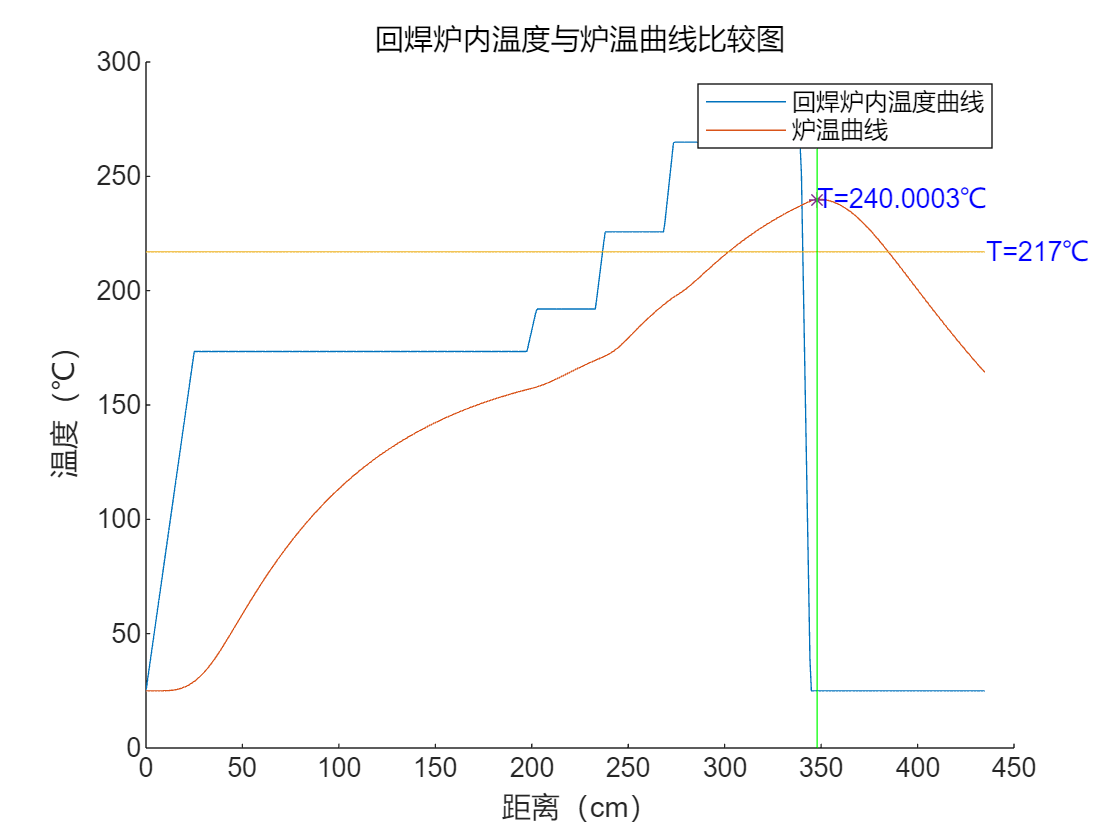

A20203

v  = v*60;

T = table(categorical({'温区 1-5 温度';'温区 6 温度';'温区 7 温度';'温区 8-9 温度';'过炉速度';'面积'}),[x(1:end-1);v;S]);
T.Properties.VariableNames = {'变量','结果'}

T = 6×2 table
        变量              结果      
    ____________    ________________

    温区 1-5 温度     173.41169878144
    温区 6 温度      191.977270007985
    温区 7 温度      225.706140690604
    温区 8-9 温度    264.996613264136
    过炉速度         88.4470421351101
    面积            403.731550065069


## **问题四的模型建立**


$$S_1 =   \left(\frac{u_m+u_n}{2}+\sum_{i=m+1}^{n-1}{(u_i-217)}\right)\Delta t \\

S_2 =   \left(\frac{u_n+u_k}{2}+\sum_{i=n+1}^{k-1}{(u_i-217)}\right)\Delta t \\

T_{m,n} = (n-m)\Delta t \\
T_{n,k} = (k-n)\Delta t\\
$$


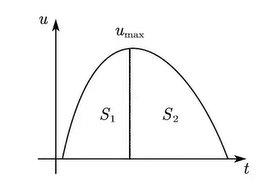

定义相似度 


$$I_s = \max \left(\frac{|S_1-S_2|}{\max(S_1,S_2)},\frac{|(k-n)-(n-m)|}{\max(k-n,n-m)}\right)$$



$$\qquad \min_{F,v} I_s = \max \left(\frac{|S_1-S_2|}{\max(S_1,S_2)},\frac{|k-2n+m|}{\max(k-n,n-m)}\right)\\
\text{使得}  \\
 \qquad \frac{|u_{i+1}-u_{i}|}{2}<3, 1\le i\le n\\
 \qquad 60\le T_1 \le 120\\
\qquad  40 \le T_2 \le 90 \\
\qquad  240 \le u_{\text{max}} \le 250\\
\qquad |F-F_0|\le 10 \\
\qquad 65\le v \le 100$$


求解模型

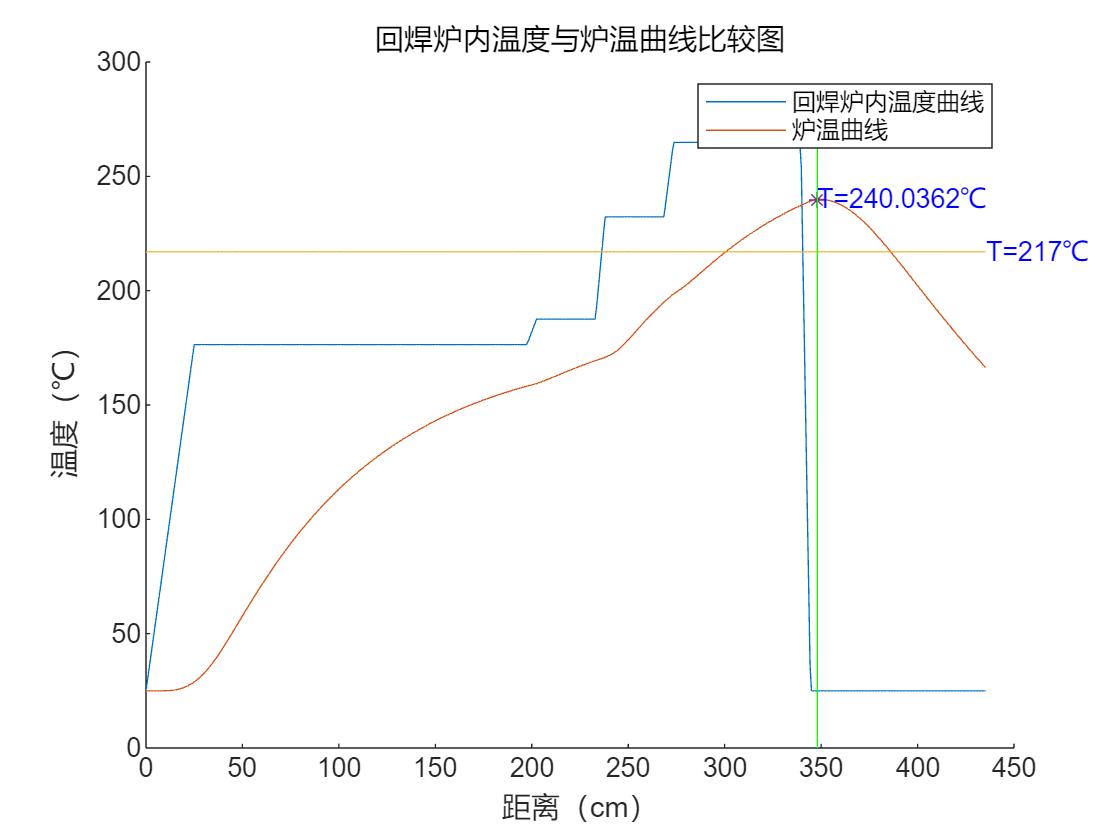

A20204

v  = v*60;

Is = max(s1,s2);
T = table(categorical({'温区 1-5 温度';'温区 6 温度';'温区 7 温度';'温区 8-9 温度';'过炉速度';'面积';'相似度'}),[x(1:end-1);v;S;Is]);
T.Properties.VariableNames = {'变量','结果'}

T = 7×2 table
        变量              结果       
    ____________    _________________

    温区 1-5 温度     176.437379283391
    温区 6 温度       187.574863049577
    温区 7 温度       232.270354776263
    温区 8-9 温度     264.837858627966
    过炉速度           90.997995529385
    面积             407.079767516845
    相似度           0.193548387096774


[目录页](matlab:open('..\MathModeling2024Spring_chap0.mlx'))  [CUMCM2022C](matlab:open('..\2022C\CUMCM2022C1.mlx')) 